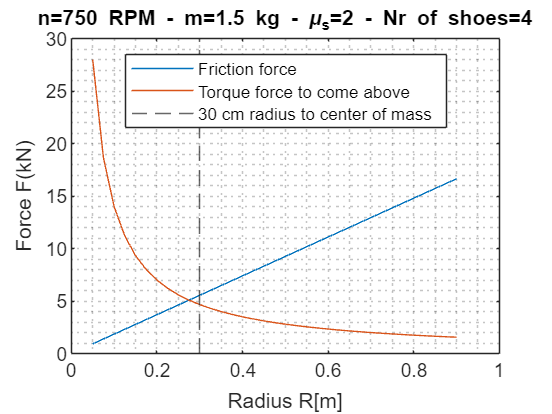

clear all
clf
format longg
m = 1.5; % kg % mass of the slinger part(shoe)
R = 0.05:0.025:0.9; %m % radius to center of gravity
n = 750; % rpm % at 50 Hz 
N = 4; % number of shoes
mu_s = 2.0; % static friction coeffecient for certain types of vulkanised rubbeer.
% https://roymech.org/Useful_Tables/Tribology/co_of_frict.html
omega = 2 * pi / 60 * n; % rad/s % vinkel hastigheden
a_n = R * omega^2; % Normal acceleration (radialt)
f_s = a_n * m * mu_s; % N %Friction force

T_max = 5600/N; % torque % divided by number of arms  
F= T_max./R; % Force due to torque % T = F*R
%For plot
title_text = "n=" + string(n) + " RPM - m=" + string(m)... 
+ " kg - \mu_{s}=" + mu_s + " - Nr of shoes=" + string(N);
plot(R,f_s/1000, DisplayName="Friction force")
hold on
title(title_text)
plot(R,F/1000, DisplayName="Torque force to come above")
xline(0.3,'--', DisplayName="30 cm radius to center of mass")
xlabel("Radius R[m]")
ylabel("Force F(kN)")
grid("minor")
legend(Location='best')
hold off